Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;
inputSize = [349, 150, 2];
inputSpecgramsFile = 'Spectrograms/specgrams-all-lin_lr.h5';
networkFileFormat = 'nets_lr/net_lr_%d';
networkIndices = [1 2 3 4 5 6 7];

dslabels = h5read(inputSpecgramsFile, '/labels');
dsinfo = h5info(inputSpecgramsFile, '/data');
dsfilenames = h5read(inputSpecgramsFile, '/filenames');
dssz = dsinfo.Dataspace.Size(1:end-1);
dslen = dsinfo.Dataspace.Size(end);
timeValues = h5read(inputSpecgramsFile, '/axis/time');
freqValues = h5read(inputSpecgramsFile, '/axis/freq');
uniqueTestHRTFNames = getUniqueHRTFsNames(dsfilenames);

for each saved network ...

dydISum = zeros([inputSize length(networkIndices)]);
dydIPosNeg = zeros([inputSize 2 length(networkIndices)]);
dydIByHRTF = zeros([inputSize 2 length(uniqueTestHRTFNames) length(networkIndices)]);

for iNetwork = networkIndices
iNetwork
currentNetwork = load(sprintf(networkFileFormat, iNetwork), 'net_lr').net_lr;

iNetwork =      1


lgraph = layerGraph(currentNetwork.Layers);
lgraph = removeLayers(lgraph, {lgraph.Layers(end).Name});
dlnet = dlnetwork(lgraph);

Calculate Average Gradient Attribution Map

tic

dydIs = zeros([inputSize dslen]);

parfor iSpecgram = 1:dslen    
	sampleSpecgrams = h5read(inputSpecgramsFile, '/data', [1, 1, 1, iSpecgram], [inputSize, 1]);
	dlImg = dlarray(single(sampleSpecgrams), 'SSC');
	dydI = abs(dlfeval(@gradientMap, dlnet, dlImg, 'softmax', dslabels(iSpecgram) + 1));
	
    dydIs(:, :, :, iSpecgram) = dydI;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).



for iSpecgram = 1:dslen  
    dydI = dydIs(:, :, :, iSpecgram);
    	
	filename = dsfilenames(iSpecgram);
    fParts = strsplit(filename, '_');
    fHRTF = fParts{2};
    iHRTF = find(strcmp(uniqueTestHRTFNames, fHRTF));
	
	iPosNeg = dslabels(iSpecgram) + 1;
	
    if(iPosNeg > 2)
    	error('wrong label')
    end
    
	dydIPosNeg(:, :, :, iPosNeg, iNetwork) = dydIPosNeg(:, :, :, iPosNeg, iNetwork) + dydI;
	dydIByHRTF(:, :, :, iPosNeg, iHRTF, iNetwork) = dydIByHRTF(:, :, :, iPosNeg, iHRTF, iNetwork) + dydI;	
	dydISum(:, :, :, iNetwork) = dydISum(:, :, :, iNetwork) + dydI;
end

end % networkIndices

dydIPosNeg = mean(dydIPosNeg, 5);
dydIByHRTF = mean(dydIByHRTF, 6);
dydISum = mean(dydISum, 4);

save('guided_backprop_lr_all', 'dydISum', 'dydIPosNeg', 'dydIByHRTF', '-v7.3')
toc

## Average Gradient Attribution Maps and Frequency Importance Curves grouped by label

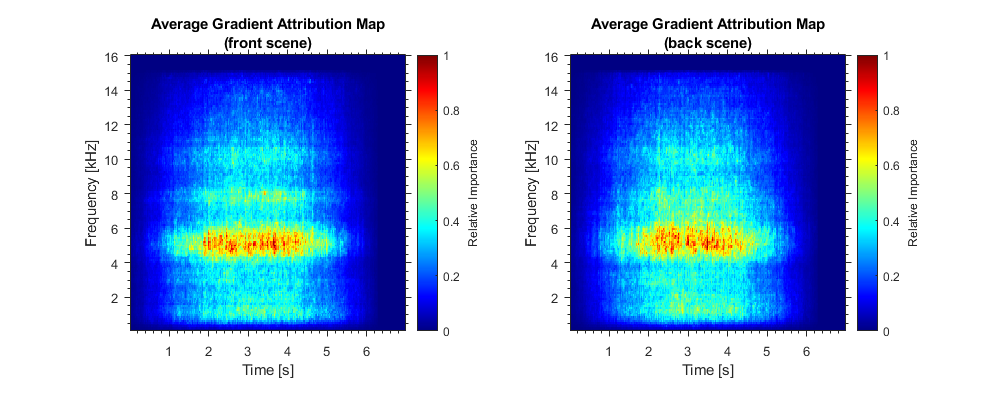

figure('Position', [0 0 1000 400])
maps = {dydIPosNeg(:, :, :, 1), dydIPosNeg(:, :, :, 2)};
mapNames = {'front scene', 'back scene'};
for iMap = 1:length(maps)
	subplot(1, 2, iMap)
	
	map = rescale(sum(abs(maps{iMap}),3));
	imagesc(timeValues, freqValues / 1000, map'); 
	colormap jet; axis xy; pbaspect([1 1 1]);
	title({'Average Gradient Attribution Map', ['(' mapNames{iMap} ')']})
	xlabel('Time [s]')
	ylabel('Frequency [kHz]')
	ylabel(colorbar, 'Relative Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
	
% 	subplot(4, 2, iMap * 2);
% 	map = rescale(sum(abs(maps{iMap}),[3, 1]));
% 	plot(freqValues / 1000, map);
% 	pbaspect([1 1 1]);
%     title({'Average Frequency Importance Curve', ['(' mapNames{iMap} ')']})
% 	xlabel('Frequency [kHz]')
% 	ylabel('Relative Importance')
% 	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% 	grid(gca,'minor')
% 	grid on
end

% subplot(4, 2, [7 8]);
% 
% map = rescale(sum(abs(dydIPosNeg(:, :, :, 1)),[3, 1]));
% plot(freqValues / 1000, map);
% 
% hold on
% map = rescale(sum(abs(dydIPosNeg(:, :, :, 2)),[3, 1]));
% plot(freqValues / 1000, map);
% 
% title(['Average Frequency Importance Curve (front & back)'])
% xlabel('Frequency [kHz]')
% ylabel('Relative Importance')
% set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% grid(gca,'minor')
% grid on
% legend({'Front', 'Back'}, 'Location', "best");
% sgtitle({'Average Gradient Attribution Map for each scene', '(all networks)'})

## Average Frequency Importance Curves grouped by HRTF

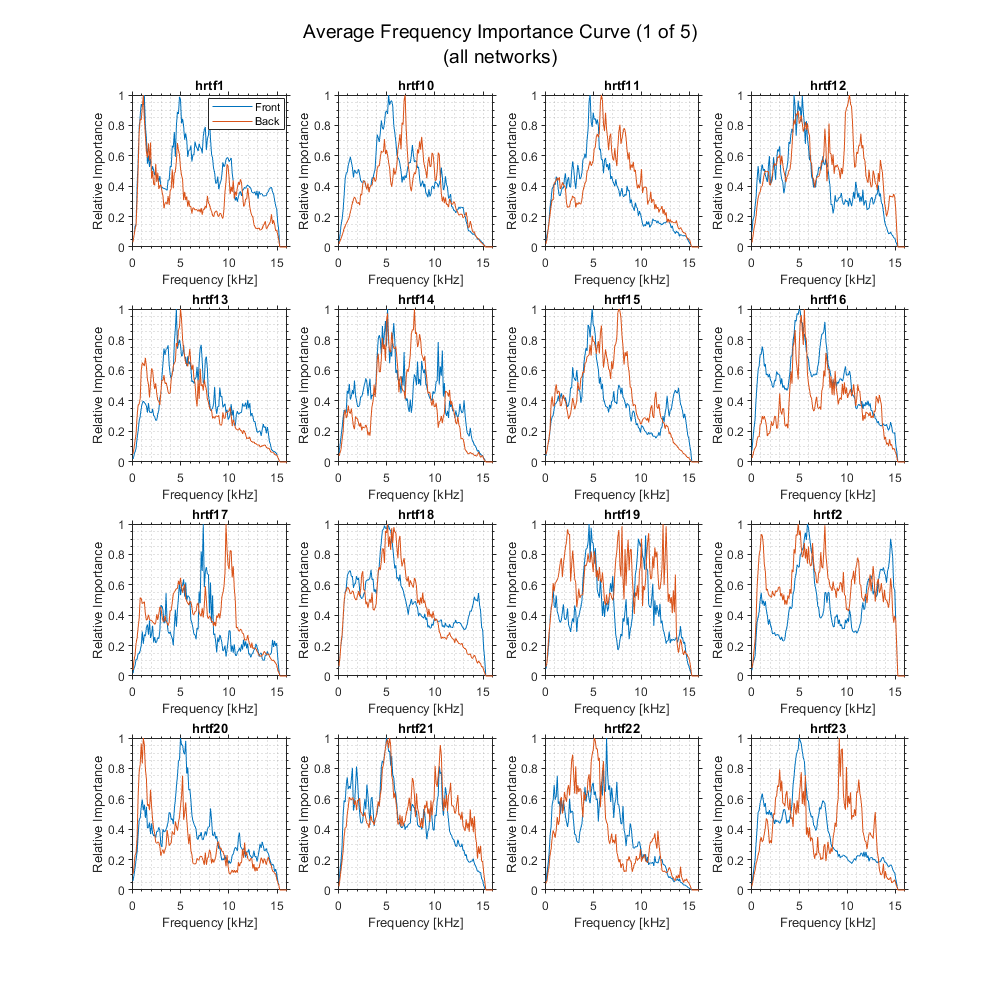

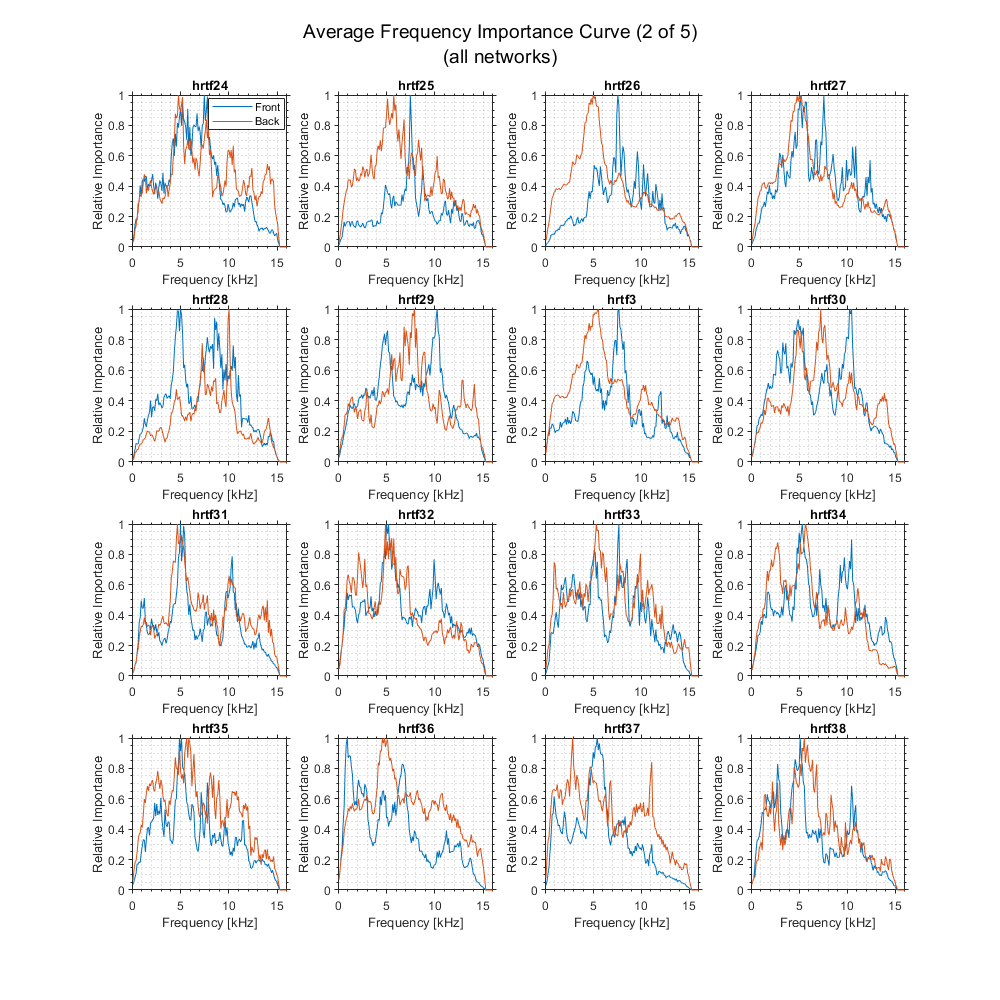

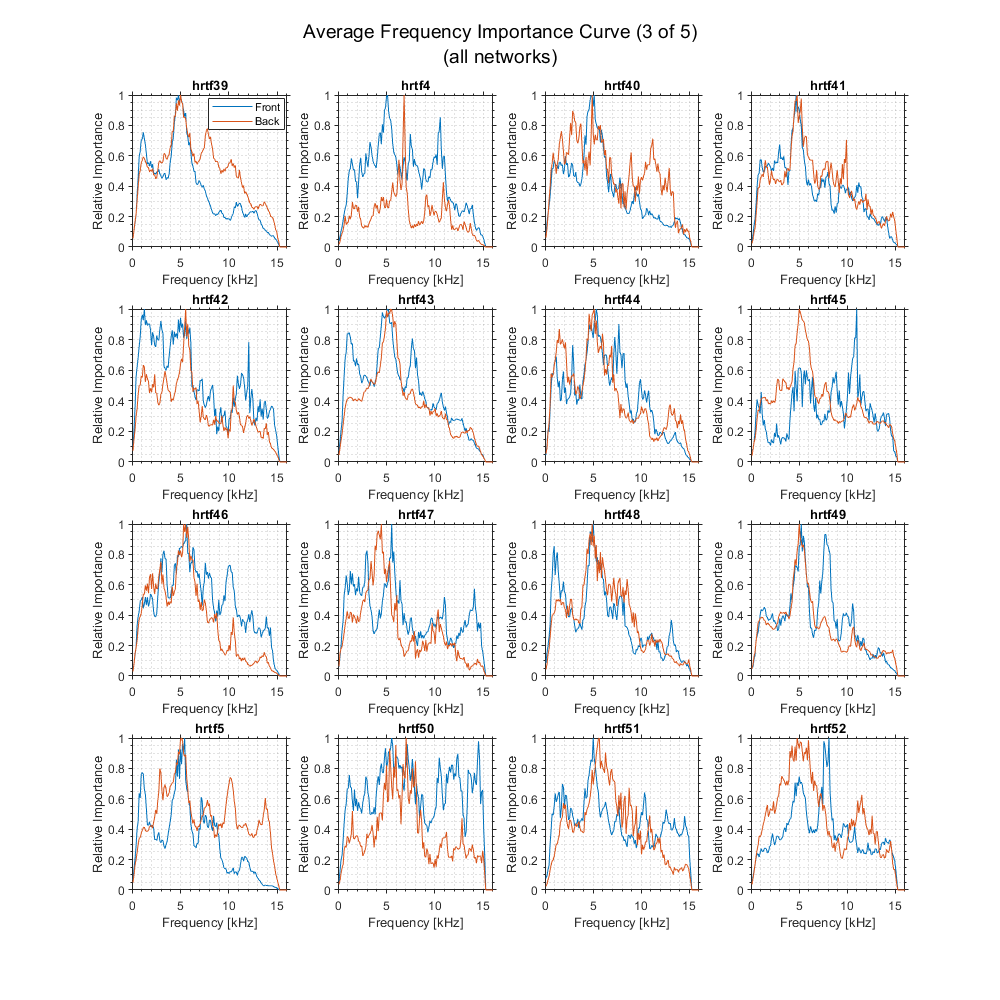

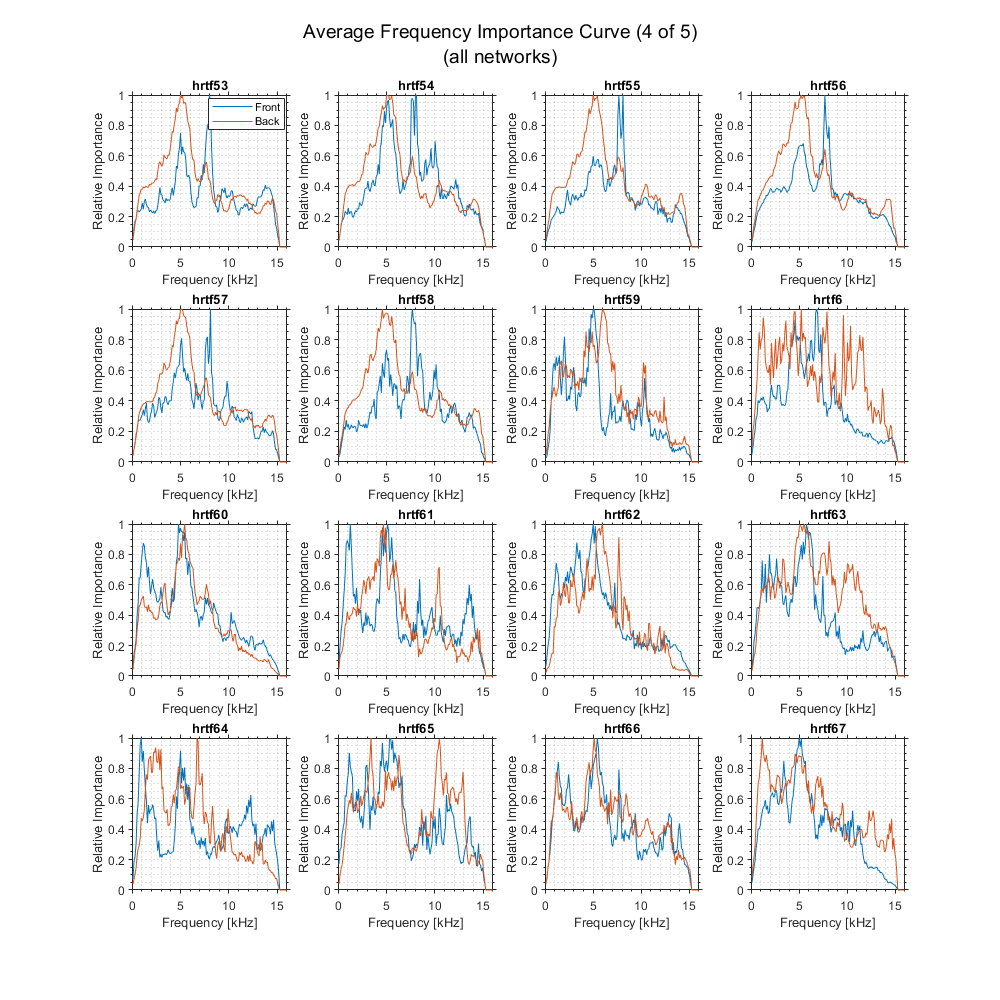

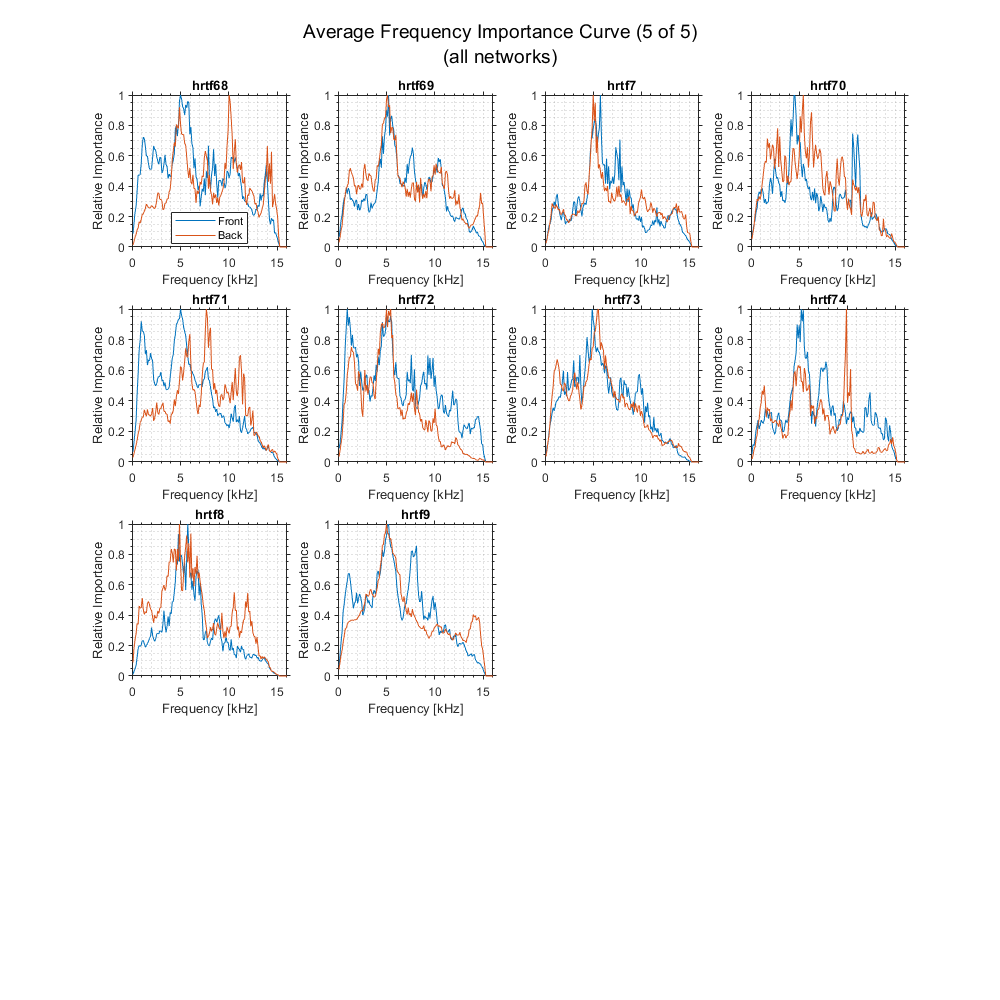

imageNames = {'Front', 'Back'};

for iHRTF = 1:length(uniqueTestHRTFNames)
	if mod(iHRTF - 1, 16) == 0
	    figure('Position', [0 0 1000 1000]);
	    sgtitle({sprintf('Average Frequency Importance Curve (%d of %d)', ...
	        ceil(iHRTF / 16), ceil(length(uniqueTestHRTFNames) / 16)), '(all networks)'});
	end
	
	subplot(4, 4, mod(iHRTF - 1, 16) + 1);
	
	map = dydIByHRTF(:, :, :, 1, iHRTF);
	map = rescale(sum(abs(map), [3, 1]));
	plot(freqValues / 1000, map);
	
	hold on
	map = dydIByHRTF(:, :, :, 2, iHRTF);
	map = rescale(sum(abs(map), [3, 1]));
	plot(freqValues / 1000, map);
	
	title(uniqueTestHRTFNames{iHRTF})
	xlabel('Frequency [kHz]')
	ylabel('Relative Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
	grid(gca,'minor')
	
	if mod(iHRTF - 1, 16) == 0
		legend(imageNames, 'Location', "best");
    end
end

## Individual Examples

rng(111)
selectedSpecgramIndices = randi(5800, 1, 7);

figure('Position', [0 0 1000 1500])

lims = {
	[1 4 6 10] 
	[1 5 6 10] 
	[1 5 3.5 8.5] 
	[1.5 4.5 7 10] 
	[2 4 6.5 10.5]
	[1.5 3.5 4 8]
	[3 6 5 9]};

for ii = 1:length(selectedSpecgramIndices)
	iSpecgram = selectedSpecgramIndices(ii);
	
	sampleSpecgrams = h5read(inputSpecgramsFile, '/data', [1, 1, 1, iSpecgram], [inputSize, 1]);
	
	dydI = guidedBackprop(dlnet, sampleSpecgrams, 'softmax', dslabels(iSpecgram) + 1);
	leftHeatmap = rescale(dydI(:, :, 1));
	rightHeatmap = rescale(dydI(:, :, 2));
	
% 	markX = 4.5; markY = 10;
	curralim = lims{ii};
	axlim = curralim(1:2);
	aylim = curralim(3:4);
	
	figure('Position', [0 0 1500 2000])
	sgtitle({strcat('Sample "', dsfilenames(iSpecgram), '"'), '(all networks)'}, 'Interpreter', 'none'); 
	
	subplot(3, 2, 1);
	imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, 1)'); 
	colormap jet; axis xy; pbaspect([1 1 1])
    title({'Frequency spectrogram', 'left channel'})
    xlabel('Time [s]')
    ylabel('Frequency [kHz]')
    ylabel(colorbar, 'Magnitude')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
	hold on; rectangle('Position', [axlim(1) aylim(1) axlim(2)-axlim(1) aylim(2)-aylim(1)]);
	
	subplot(3, 2, 2);	
	imagesc(timeValues, freqValues / 1000, leftHeatmap'); 
	colormap jet; axis xy; pbaspect([1 1 1]);
	title({'Gradient Attribution Map', 'left channel'})
	xlabel('Time [s]')
	ylabel('Frequency [kHz]')
	ylabel(colorbar, 'Relative Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
	hold on; rectangle('Position', [axlim(1) aylim(1) axlim(2)-axlim(1) aylim(2)-aylim(1)], 'EdgeColor', 'w');
	
	

Zoom left channel

	subplot(3, 2, 3);
	imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, 1)'); 
	colormap jet; axis xy; pbaspect([1 1 1])
    title({'Frequency spectrogram', 'left channel'})
    xlabel('Time [s]')
    ylabel('Frequency [kHz]')
    ylabel(colorbar, 'Magnitude')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% 	hold on; plot(markX, markY, 'ko', 'MarkerSize', 30, 'LineWidth', 2)
	xlim(axlim)
	ylim(aylim)
	hold on; 	
	[C, h] = imcontour(timeValues, freqValues / 1000, leftHeatmap', 2, 'm'); h.LineWidth = 1;
	
	subplot(3, 2, 4);
	imagesc(timeValues, freqValues / 1000, leftHeatmap'); 
	colormap jet; axis xy; pbaspect([1 1 1]);
	title({'Gradient Attribution Map', 'left channel'})
	xlabel('Time [s]')
	ylabel('Frequency [kHz]')
	ylabel(colorbar, 'Relative Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% 	hold on; plot(markX, markY, 'ko', 'MarkerSize', 30, 'LineWidth', 2)
	xlim(axlim)
	ylim(aylim)
	hold on; 
	[C, h] = imcontour(timeValues, freqValues / 1000, leftHeatmap', 2, 'm'); h.LineWidth = 1;

Zoom right channel

	subplot(3, 2, 5);
	imagesc(timeValues, freqValues / 1000, sampleSpecgrams(:, :, 2)'); 
	colormap jet; axis xy; pbaspect([1 1 1])
    title({'Frequency spectrogram', 'right channel'})
    xlabel('Time [s]')
    ylabel('Frequency [kHz]')
    ylabel(colorbar, 'Magnitude')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% 	hold on; plot(markX, markY, 'ko', 'MarkerSize', 30, 'LineWidth', 2)
	xlim(axlim)
	ylim(aylim)
	hold on; 	
	[C, h] = imcontour(timeValues, freqValues / 1000, rightHeatmap', 2, 'm'); h.LineWidth = 1;
	
	subplot(3, 2, 6);
	imagesc(timeValues, freqValues / 1000, rightHeatmap'); 
	colormap jet; axis xy; pbaspect([1 1 1]);
	title({'Gradient Attribution Map',  'right channel'})
	xlabel('Time [s]')
	ylabel('Frequency [kHz]')
	ylabel(colorbar, 'Relative Importance')
	set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', 'TickDir', 'out', 'TickLength', [0.02 0.025])
% 	hold on; plot(markX, markY, 'ko', 'MarkerSize', 30, 'LineWidth', 2)
	xlim(axlim)
	ylim(aylim)
	hold on; 
	[C, h] = imcontour(timeValues, freqValues / 1000, rightHeatmap', 2, 'm'); h.LineWidth = 1;
end

Error using h5readc
Unable to open '/ramdisk2/Spectrograms/specgrams-all-lin-lr-d7.h5'. File or folder not found.

Error in h5read (line 93)
[data,var_class] = h5readc(Filename,Dataset,start,count,stride);

function dydI = guidedBackprop(dlnet, imgs, softmaxName, classIdx)
	dlImgs = dlarray(single(imgs), 'SSC');
	dydI = extractdata(abs(dlfeval(@gradientMap, dlnet, dlImgs, softmaxName, classIdx)));
end

function dydI = gradientMap(dlnet, dlImgs, softmaxName, classIdx)
	% Compute the gradient of a class score with respect to one or more input
	% images.
	
	dydI = dlarray(zeros(size(dlImgs)));
	
	for i=1:size(dlImgs,4)
	    I = dlImgs(:,:,:,i);
	    scores = predict(dlnet,I,'Outputs',{softmaxName});
	    classScore = scores(classIdx);
	    dydI(:,:,:,i) = dlgradient(classScore,I);
	end
end